## Splines (when lsf polynomial approximation fails...)

**Example. **Let us consider the function

$f(x) = \frac{1}{1+25x^2}$,

on the interval $-1\le x\le 1$, and a sample of points given by the abscisses $x_{i} = -1 + 0.2(i-1)$, and their corresponding values $y=f(y_{i})$, $i=1,\dots,N=11$.

clearvars
close all

a = -1.0; b = 1.0; N = 10; M = 200;
f = @(x) 1./(1 + 25*x.^2);

%Partitions

%Coarse partition
xN = linspace(a,b,N+1); fN = f(xN); 

%Finer partition
xM = linspace(a,b,M+1); M1 = length(xM); fM = f(xM);

%Linear spline (polygonal): interp1
lM = interp1(xN,fN,xM);
figure()
set(gcf,'defaultTextInterpreter','LaTeX')
subplot(1,2,1)
plot(xN,fN,'o',...
        'Marker','o',...
        'MarkerFaceColor','black',...
        'MarkerEdgeColor',...
        'black',...
        'MarkerSize', 2, ...
        'lineWidth',1)
title('1D Linear spline approximation')
hold on
plot(xM,fM,'-','color','red')
plot(xM,lM,"LineStyle",'-','color','blue')
xlabel('$x$')
ylabel('$y\quad$','rot', 360)
ymax = max([fM,lM]);
ymin = min([fM,lM])-0.1;
axis([-1,1,ymin,ymax])
pbaspect([1 1 1])
hold off

### Cubic Splines

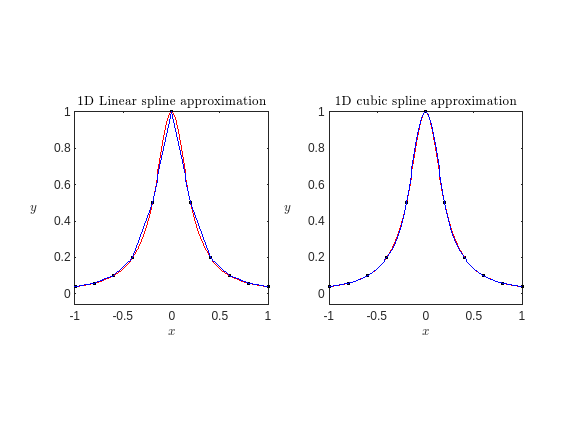


sM = spline(xN,fN,xM);
subplot(1,2,2)
plot(xN,fN,'o',...
        'Marker','o',...
        'MarkerFaceColor','black',...
        'MarkerEdgeColor',...
        'black',...
        'MarkerSize', 2, ...
        'lineWidth',1)
title('1D cubic spline approximation')
hold on
plot(xM,fM,'-','color','red')
plot(xM,sM,"LineStyle",'-','color','blue')
xlabel('$x$')
ylabel('$y\quad$','rot', 360)
ymax = max([fM,sM]);
ymin = min([fM,sM])-0.1;
axis([-1,1,ymin,ymax])
pbaspect([1 1 1])
hold off

### Errors

format short e
format compact

%Create a table
MeanErr = [norm(fM-lM,1)/M1; norm(fM-sM)/M1];
MaxErr = [norm(fM-lM,Inf); norm(fM-sM,Inf)];

ErrSplines = array2table([MeanErr, MaxErr],...
    'VariableNames',{'Mean Err.','Max. Err.'},...
    'RowNames',{'Linear Spline';'Cubic Spline'});

ErrSplines = table(ErrSplines,'VariableNames',{'Mean and Max Errors'}); % Nested table

disp(ErrSplines);

               Mean and Max Errors           
                     Mean Err.     Max. Err. 
    _________________________________________
    Linear Spline    1.4974e-02    6.7431e-02
    Cubic Spline     5.0490e-04    2.1960e-02
